Climb rate

Ts_hev = 1/100;
% Requirments
Mp = 0.1

Mp = 0.1000

tr = 0.5;
zeta = sqrt((log(Mp)^2)/(log(Mp)^2+pi^2))

zeta = 0.5912

wn = 1.8/(tr);

p_s_want = [-zeta*wn + 1i*wn*sqrt(1-zeta^2);
            -zeta*wn - 1i*wn*sqrt(1-zeta^2)]

p_s_want =   -2.1282 + 2.9036i
  -2.1282 - 2.9036i



p_z_want = exp(p_s_want*Ts_hev)

p_z_want =    0.9785 + 0.0284i
   0.9785 - 0.0284i



% Plant
A_hev = [-1/t_P,  0, 0;
          1/m(1), 0, 0;
          0,      1, 0];

b_hev = [1/t_P; 0; 0];
c_climb = [0, 1, 0];
d_climb = 0;

sysC = ss(A_hev,b_hev,c_climb,d_climb);
sysD_climb = c2d(sysC,Ts_hev,'zoh');

Ki = 21.791

Ki = 21.7910

Kp = Ki*6

Kp = 130.7460

% Ki = 20

C_climb = pid(Kp,Ki,0,0,Ts_hev)

C_climb =
 
              Ts  
  Kp + Ki * ------
              z-1 

  with Kp = 131, Ki = 21.8, Ts = 0.01
 
Sample time: 0.01 seconds
Discrete-time PI controller in parallel form.



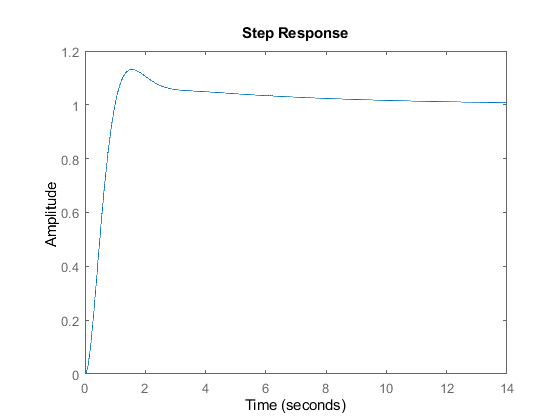

% [C_climb,info] = pidtune(sysD_climb,'PID')
step(feedback(C_climb*sysD_climb,1))


% Equivalent plant
A_clm = [A_hev-b_hev*C_climb.Kp*c_climb, b_hev*C_climb.Ki;
         -c_climb              , 0];
b_clm = [b_hev*C_climb.Kp;1];


Altitude

% Requirments
zeta = 1

zeta = 1

ts2 = 2;
wn = 4/(zeta*ts2);

p_s_want = [-zeta*wn + 1i*wn*sqrt(1-zeta^2);
            -zeta*wn - 1i*wn*sqrt(1-zeta^2)]

p_s_want =     -2
    -2



p_z_want = exp(p_s_want*Ts_hev)

p_z_want =     0.9802
    0.9802



% Plant
c_alt = [0,0,1,0];
d_alt = 0;

sysC = ss(A_clm,b_clm,c_alt,d_alt);
sysD_alt = c2d(sysC,Ts_hev,'zoh');

Kp = 0.8

Kp = 0.8000

Ki = 0

Ki = 0

C_alt = pid(Kp,Ki,0,0,Ts_hev)

C_alt =
 
  Kp = 0.8
 
P-only controller.



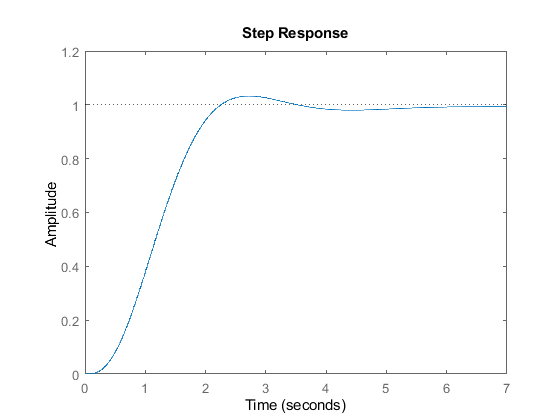


% [C_alt, info] = pidtune(sysD_alt,'P')
step(feedback(C_alt*sysD_alt,1))